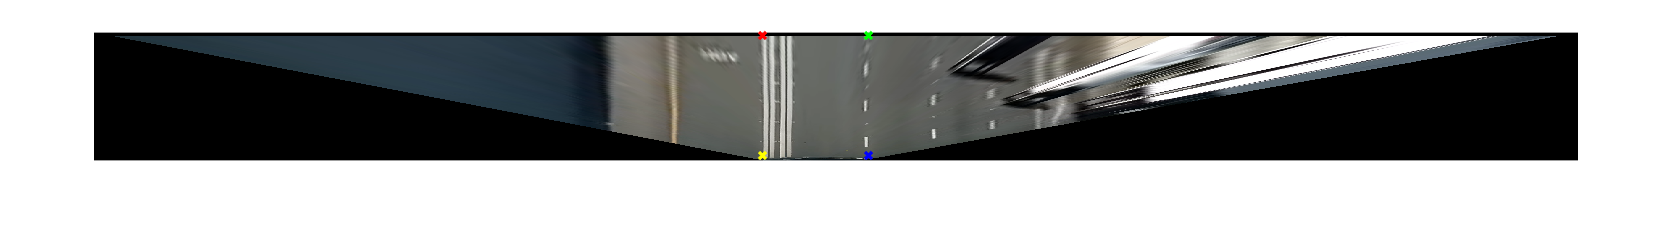

img = imread("test_imgs\img2.png");
[Iwarp, H, Rout] = transform_to_birds_eye(img,400);
imshow(Iwarp)
[pa, pb, pc, pd] = arbitrarily_selected_points;

[paT(1), paT(2)] = transformPointsForward(H,pa(1),pa(2));
[pbT(1), pbT(2)] = transformPointsForward(H,pb(1),pb(2));
[pcT(1), pcT(2)] = transformPointsForward(H,pc(1),pc(2));
[pdT(1), pdT(2)] = transformPointsForward(H,pd(1),pd(2));

hold on
plot(paT(1)-Rout.XWorldLimits(1),paT(2)-Rout.YWorldLimits(1),'x','LineWidth',2,'Color','red');
plot(pbT(1)-Rout.XWorldLimits(1),pbT(2)-Rout.YWorldLimits(1),'x','LineWidth',2,'Color','green');
plot(pcT(1)-Rout.XWorldLimits(1),pcT(2)-Rout.YWorldLimits(1),'x','LineWidth',2,'Color','blue');
plot(pdT(1)-Rout.XWorldLimits(1),pdT(2)-Rout.YWorldLimits(1),'x','LineWidth',2,'Color','yellow');
hold off